# Runge Kutta method of 3rd order

clear all, clc

%Initial conditions
t(1) = 0;
x(1) = 1;

% simulation parameters
t_f = 1 ;  
h = .1;  % step size

f = @(x,t) 3*x*(2*t-1)   % Function to be integrated or ODE in RHS 

f = function_handle with value:
    @(x,t)3*x*(2*t-1)


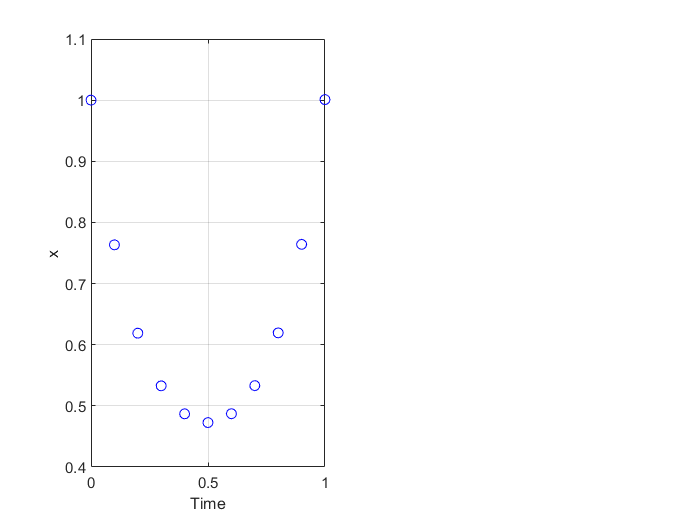


% RK 4 loop

for i= 1:ceil(t_f/h)
    
    %update t
    t(i+1) = t(i) + h;
    
    %update x
    s1 = h*f(x(i),t(i));
    s2 = h*f(x(i) + 0.5*s1, t(i) + 0.5*h);
    s3 = h*f(x(i) -s1 + 2*s2, t(i) + h);
    
    
    x(i+1) = x(i) + 1/6 *(s1 + 4*s2 + s3);
end

figure(1)
subplot(1,2,1)
plot(t,x, 'bo')
grid on , hold on
xlabel('Time')
ylabel('x')

## classical solution

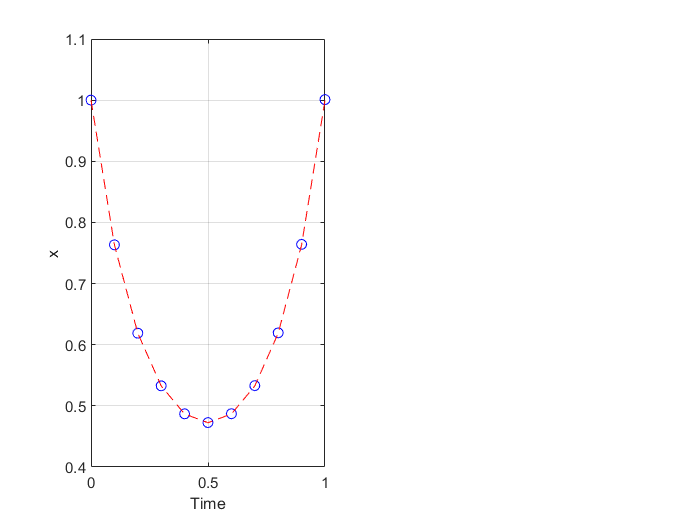

subplot(1,2,1)
g = exp(3.*t.^2 -3*t);
plot(t,g,'r--')